# 绘制路面分级图

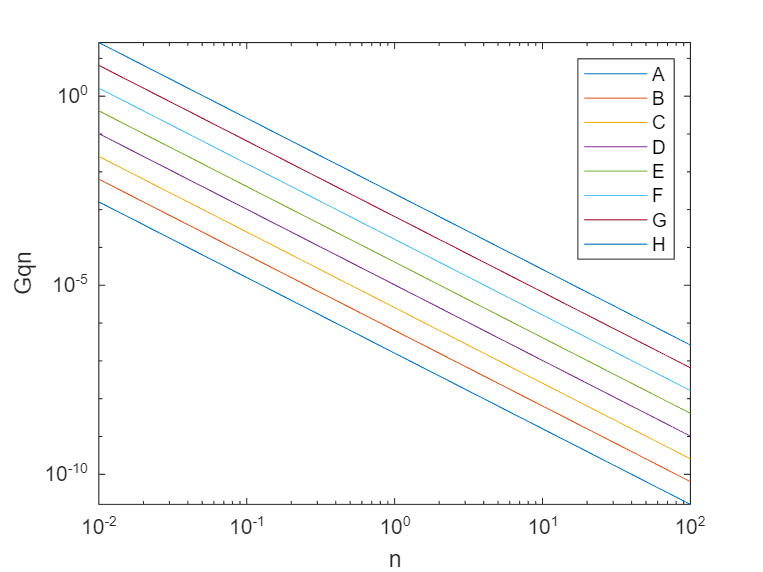

clc
clear 
close all

% 基本参数设置
w    = 2;
n0   = 0.1;
n    = linspace(0.01,100,100);
Gqn0 = [16,64,256,1024,4096,16384,65536,262144]*1e-6;
Gqn  = ones(length(Gqn0),length(n));

% 计算Gqn
for k = 1:length(Gqn0)
    Gqn(k,:) = Gqn0(k)*(n/n0).^(-w);
end


% 绘制双对数坐标图
figure(1)
loglog(n,Gqn)

xlabel('n')
ylabel('Gqn')

legend('A','B','C','D','E','F','G','H')